## EEL839 - Transmissão Digital

## Parte 2 - Treinamento da rede neural e ataque FGSM

Trabalho sobre o artigo: Adversarial training based channel estimation to mitigate jamming attacks in OFDM systems

Guilherme Araujo Thomaz

Este código implementa a parte do trabalho referente à geração de gráficos.

## 1 - Estimação por LS

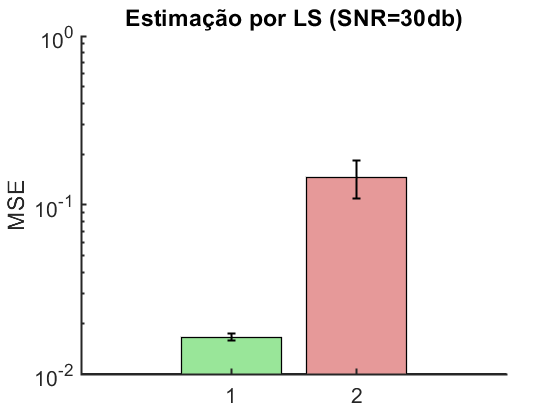

%X = categorical({'Pubicação insegura','Publicação segura','Consulta insegura','Consulta segura'});
%X = reordercats(X,{'Pubicação insegura','Publicação segura','Consulta insegura','Consulta segura'});
X = [1 2];
Y = [0.0165 0.1454];
erro = [7.93e-4 0.0368];
hbar = bar(X,Y,'FaceColor','flat');
hbar.CData(2,:) = [.9 0.6 .6];
hbar.CData(1,:) = [.6 0.9 .6];
hbar.LineWidth = 1;
ylim([10e-3 1])
set(gca,'YScale','log')
hold on
err = errorbar(Y,erro);
err.LineWidth = 1.5;
err.Color = [0 0 0];
err.LineStyle = 'none';
t = title('Estimação por LS (SNR=30db)');
t.FontSize = 16;
yl = ylabel('MSE');
yl.FontSize = 16;
yl.FontSize = 16;
H=gca;
H.LineWidth = 1.5;
set(gca,'FontSize',16)
box off
hold off

## 2 - Rede neural vulnerável

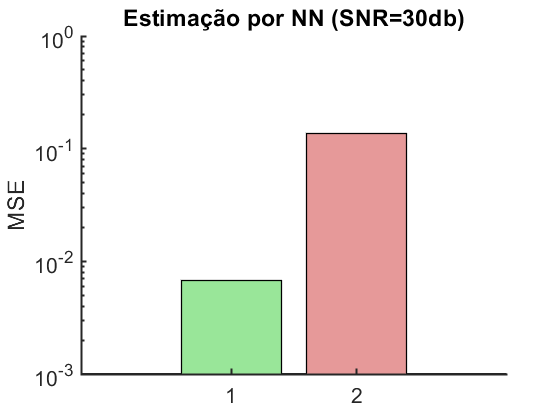

%X = categorical({'Pubicação insegura','Publicação segura','Consulta insegura','Consulta segura'});
%X = reordercats(X,{'Pubicação insegura','Publicação segura','Consulta insegura','Consulta segura'});
X = [1 2];
Y = [0.0068 0.1356];
hbar = bar(X,Y,'FaceColor','flat');
hbar.CData(2,:) = [.9 0.6 .6];
hbar.CData(1,:) = [.6 0.9 .6];
hbar.LineWidth = 1;
ylim([10e-4 1])
set(gca,'YScale','log')
hold on
t = title('Estimação por NN (SNR=30db)');
t.FontSize = 16;
yl = ylabel('MSE');
yl.FontSize = 16;
yl.FontSize = 16;
H=gca;
H.LineWidth = 1.5;
set(gca,'FontSize',16)
box off
hold off

## 3 - Variação da SNR

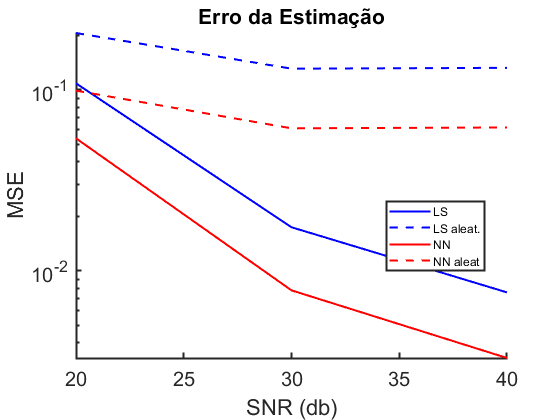

X = [20 30 40];
ls = [0.1084 0.0174 0.0076];
ls_rand = [0.2057 0.1307 0.1321];
nn = [0.0539 0.0078 0.0033];
nn_rand = [0.0988 0.0612 0.0619];

% Defina cores personalizadas para cada linha
cor_ls = 'b';         % Azul
cor_ls_rand = 'b';    
cor_nn = 'r';         % Vermelho
cor_nn_rand = 'r';    

figure;

% Plote as curvas com as cores personalizadas e escala logarítmica no eixo y
semilogy(X, ls, 'LineWidth', 1.5, 'Color', cor_ls);
hold on;
semilogy(X, ls_rand, 'LineWidth', 1.5, 'Color', cor_ls_rand, 'LineStyle', '--');
semilogy(X, nn, 'LineWidth', 1.5, 'Color', cor_nn);
semilogy(X, nn_rand, 'LineWidth', 1.5, 'Color', cor_nn_rand, 'LineStyle', '--');

t = title('Erro da Estimação');
t.FontSize = 16;

x = xlabel('SNR (db)');
x.FontSize = 16;

y = ylabel('MSE');
y.FontSize = 16;

% Aumente a espessura das linhas dos eixos
ax = gca;
ax.LineWidth = 1.5;

ax.XAxis.FontSize = 15;
ax.YAxis.FontSize = 15;


box off

% Adicione uma legenda
legend('LS', 'LS aleat.', 'NN', 'NN aleat', 'Location', 'Best');

## 4 - Variação da potência do ruído de ataque

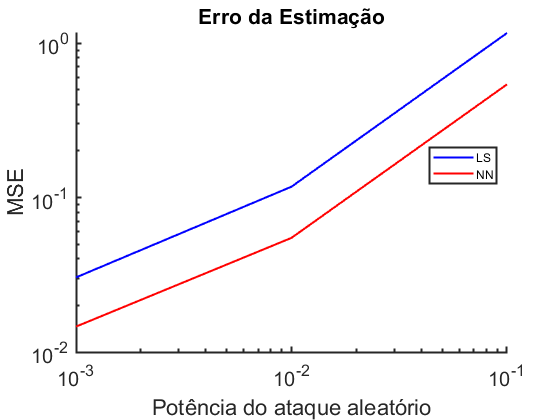

X = [10^-3 10^-2 10^-1];
ls = [0.0304 0.1175 1.1609];
nn = [0.0146 0.0548 0.5398];

% Defina cores personalizadas para cada linha
cor_ls = 'b';         % Azul
cor_nn = 'r';         % Vermelho

figure;

% Plote as curvas com as cores personalizadas e escala logarítmica no eixo y
loglog(X, ls, 'LineWidth', 1.5, 'Color', cor_ls);
hold on;
loglog(X, nn, 'LineWidth', 1.5, 'Color', cor_nn);

t = title('Erro da Estimação');
t.FontSize = 16;

x = xlabel('Potência do ataque aleatório');
x.FontSize = 16;

y = ylabel('MSE');
y.FontSize = 16;

% Aumente a espessura das linhas dos eixos
ax = gca;
ax.LineWidth = 1.5;

ax.XAxis.FontSize = 15;
ax.YAxis.FontSize = 15;

box off

% Adicione uma legenda
legend('LS', 'NN', 'Location', 'Best');

## 5 - Ataque FGSM

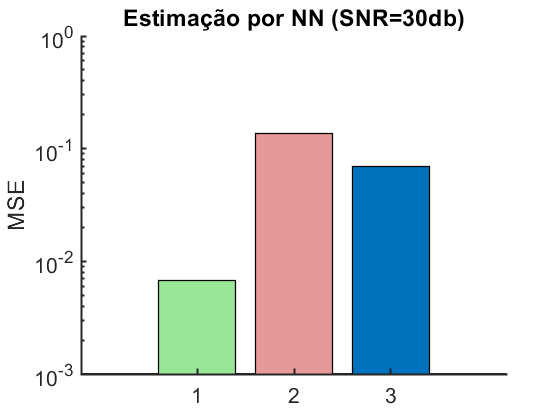

X = [1 2 3];
Y = [0.0068 0.1356 0.0688];
hbar = bar(X,Y,'FaceColor','flat');
hbar.CData(2,:) = [.9 0.6 .6];
hbar.CData(1,:) = [.6 0.9 .6];
hbar.LineWidth = 1;
ylim([10e-4 1])
set(gca,'YScale','log')
hold on
t = title('Estimação por NN (SNR=30db)');
t.FontSize = 16;
yl = ylabel('MSE');
yl.FontSize = 16;
yl.FontSize = 16;
H=gca;
H.LineWidth = 1.5;
set(gca,'FontSize',16)
box off
hold off

## 6 - FGSM 2

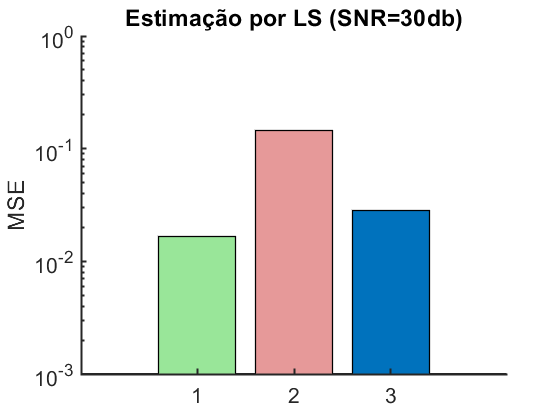

X = [1 2 3];
Y = [0.0165 0.1454 0.0284];
hbar = bar(X,Y,'FaceColor','flat');
hbar.CData(2,:) = [.9 0.6 .6];
hbar.CData(1,:) = [.6 0.9 .6];
hbar.LineWidth = 1;
ylim([10e-4 1])
set(gca,'YScale','log')
hold on
t = title('Estimação por LS (SNR=30db)');
t.FontSize = 16;
yl = ylabel('MSE');
yl.FontSize = 16;
yl.FontSize = 16;
H=gca;
H.LineWidth = 1.5;
set(gca,'FontSize',16)
box off
hold off

## 7 - Treinamento Adversarial Típico

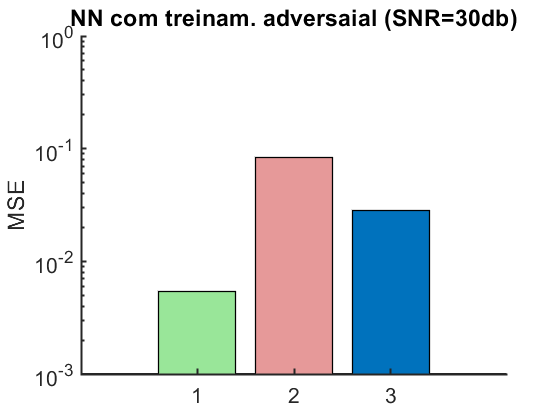

X = [1 2 3];
Y = [0.0054 0.0834 0.028];
hbar = bar(X,Y,'FaceColor','flat');
hbar.CData(2,:) = [.9 0.6 .6];
hbar.CData(1,:) = [.6 0.9 .6];
hbar.LineWidth = 1;
ylim([10e-4 1])
set(gca,'YScale','log')
hold on
t = title('Estimação com NN robusta (SNR=30db)');
t.FontSize = 16;
yl = ylabel('MSE');
yl.FontSize = 16;
yl.FontSize = 16;
H=gca;
H.LineWidth = 1.5;
set(gca,'FontSize',16)
box off
hold off

## 8 - Treinamento Adversarial Proposto

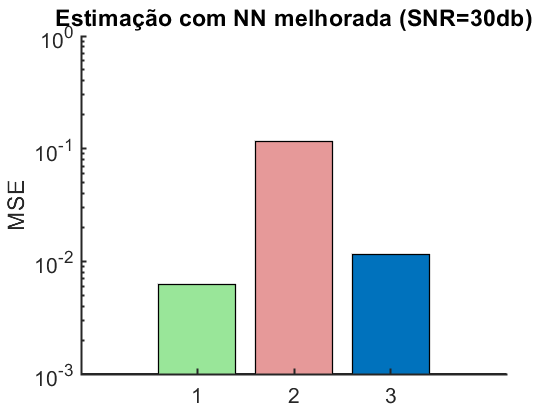

X = [1 2 3];
Y = [0.0062 0.1154 0.0116];
hbar = bar(X,Y,'FaceColor','flat');
hbar.CData(2,:) = [.9 0.6 .6];
hbar.CData(1,:) = [.6 0.9 .6];
hbar.LineWidth = 1;
ylim([10e-4 1])
set(gca,'YScale','log')
hold on
t = title('Estimação com NN melhorada (SNR=30db)');
t.FontSize = 16;
yl = ylabel('MSE');
yl.FontSize = 16;
yl.FontSize = 16;
H=gca;
H.LineWidth = 1.5;
set(gca,'FontSize',16)
box off
hold off